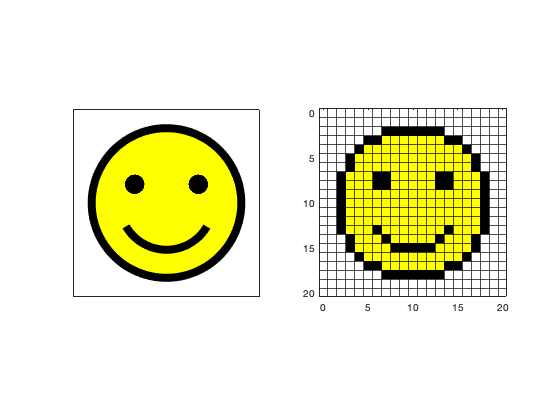

% Idealised image
face_c = [0.5, 0.5];
face_r = 0.4;
eye1_c = [0.33, 0.6];
eye2_c = [0.67, 0.6];
eye_r = 0.05;

% Create raster
Nx = 20;
Ny = 20;
R = 255 * ones(Ny, Nx, 3);

R = drawcircle(R, round(Nx * face_c(1)), round(Ny * face_c(2)), round(Nx * face_r), [0;0;0]);
R = floodfill(R, 10, 10, [255;255;255], [255;255;0]);
for i = 1 : 3
    R(7:8, 6:7, i) = 0;
    R(7:8, 13:14, i) = 0;
    R(13,6,i) = 0;
    R(14,7,i) = 0;
    R(15,8:12,i) = 0;
    R(14,13,i) = 0;
    R(13,14,i) = 0;
end

% Plot idealised image
subplot(1, 2, 1)

theta = 0 : pi / 200 : 2 * pi;
x = face_c(1) + face_r * cos(theta);
y = face_c(2) + face_r * sin(theta);
patch(x, y, 'y')
hold on
plot(x, y, color='k', LineWidth=8);

x = eye1_c(1) + eye_r * cos(theta);
y = eye1_c(2) + eye_r * sin(theta);
fill(x, y, 'k');

x = eye2_c(1) + eye_r * cos(theta);
y = eye2_c(2) + eye_r * sin(theta);
fill(x, y, 'k');

theta = deg2rad(210) : pi / 200 : deg2rad(330);
x = 0.5 + 0.25 * cos(theta);
y = 0.5 + 0.25 * sin(theta);
plot(x, y, color='k', LineWidth=8);

hold off

xticks([])
yticks([])
axis equal
box on
axis([0, 1, 0, 1])

% Plot raster
subplot(1, 2, 2)
image(R)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1);
    yline(row-0.5, Color='k', LineWidth=1);
end
hold off

axis equal
axis([-0.5, Nx+0.5, -0.5, Ny+0.5])

exportgraphics(gcf,'ideal_and_raster_image.png','Resolution',300) 